## Теория

Система уравнений, по которой строится модель:


$$\begin{cases}
U+\epsilon=RI+L \frac{dI}{dt} \\
M+M_{ext}=J\frac{d\omega}{dt}+\lambda\omega \\
M=K_mI \\
\epsilon=-K_\omega\omega
\end{cases}$$



$$U - напряжение,\ В \\
\epsilon - ЭДС\ самоиндукции,\ В \\
R -сопротивление,\ Ом \\
I - ток,\ А \\
L - индуктивность,\ Гн \\
M - момент\ двигателя,\ Н\cdotм \\
M_{ext} - момент\ внешней\ нагрузки\ на\ валу\ двигателя,\ Н\cdotм \\
J-момент\ инерции\ ротора,\ кг\cdot м^2 \\
\omega - угловая\ скорость,\ \frac{рад}{с} \\
\lambda - коэффициент\ трения \\
K_m - постоянная\ момента,\ \frac{Н\cdotм}{А} \\
K_{\omega} - постоянная\ ЭДС,\ \frac{В\cdotс}{рад}
$$


Система уравнений записывается в форме "вход - состояние - выход":


$$\dot{x}=Ax+Bu \\
y = Cx+Du$$


Здесь $x$ - вектор состояния, $\dot{x}$ - скорость изменения вектора состояния, матрица $A$ "описывает поведение" модели, матрица $B$ - описывает влияение управления на систему, $u$ - управление, $y$ - выход системы, матрица $C$- выбор элемента вектора состояния, который хотим измерять, матрица $D$ описывает влияние управления на выход системы. Обычно $D$ принимают 0.

Первая строка "вход-состояние", потому что в ней присутствует вход в модель (управление) - $u$, и состояние - $x$. Вторая строка "выход", потому что там присутствует $y$ - выход системы. По сути то, что мы измеряем датчиками.

Представить модель в данной форме можно разными способами, в зависимости от выбора вектора состояния. Например, можно взять вектор состояния в виде тока и угловой скорости.

syms w I
x = [w ; I]

$$x = \left(\begin{array}{c} w\\ \text{I} \end{array}\right)$$

Выбор вектора состояния зависит от целей. Чем больше элементов мы добавляем (при условии, что мы можем их описать уравнениями), тем больше информации о системе у нас будет, но тем больше нужно будет проводить вычислений.

Любую модель можно представить в форме "вход - состояние - выход" и использовать готовые инструменты для работы с моделью. Например в simulink есть блок State-Space. В его параметры записываются матрицы A B C D и задаются начальные значения вектора состония. 

## Практика

Это параметры из даташита случайного привода maxon. Номинальное напряжение 12 В. Холостой ход - подали 12 В, на валу нет внешней нагрузки. Номинальная угловая скорость - 12 В при номинальной нагрузке.

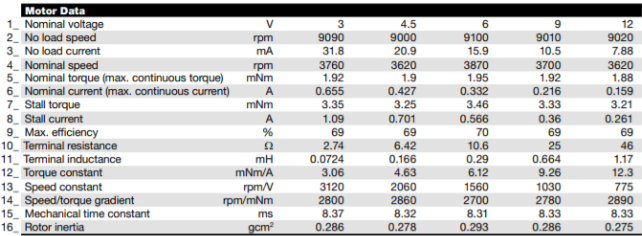

### Записываем все переменные

clear;
clc;

J = 0.275e-7 % момент инерции ротора

J = 2.7500e-08

R = 46; % сопротивление
L = 1.17e-3 % индукция

L = 0.0012

Kw = 0.012 % постоянная ЭДС

Kw = 0.0120

Km = 12.3e-3 % постоянная момента

Km = 0.0123

Ihh = 7.88e-3 % ток холостого хода

Ihh = 0.0079

Whh = pi/30*9020 %rad/s (9020 rpm / 60 * 2 * pi) % скорость холостого хода

Whh = 944.5722

Lam = Km*Ihh/Whh %лямбда - коэффициент трения (??? переход от скорости к моменту???)

Lam = 1.0261e-07

Wnominal = pi/30 * 3620 % номинальная угловая скорость

Wnominal = 379.0855

Mhh = Km*Ihh

Mhh = 9.6924e-05


A = [-Lam/J Km/J; -Kw/L -R/L]

A = 1.0e+05 *

   -0.0000    4.4727
   -0.0001   -0.3932


B = [-1/J 0; 0 1/L]

B = 1.0e+07 *

   -3.6364         0
         0    0.0001


C = [1 0; 0 1]

C =      1     0
     0     1


D = [0 0; 0 0]

D =      0     0
     0     0



theta = [L; R; Kw; J; Lam]

theta =     0.0012
   46.0000
    0.0120
    0.0000
    0.0000



Amp = 6;
Bias = 6;
W = 6;
fi = 3.1415;
Mext = 0;

Const_input = [Amp Bias W fi Mext];

betta = 2 % коэффициент регуляризации

betta = 2

k0 = 100 % начальное значение матрицы коэффициентов

k0 = 100

I = eye(5) % диагональная единичная матрица

I =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


GAMMA_0 = k0.*I % матрица начальных значений коэффициентов

GAMMA_0 =    100     0     0     0     0
     0   100     0     0     0
     0     0   100     0     0
     0     0     0   100     0
     0     0     0     0   100


### Проводим симуляцию и выводим графики

out1 = sim('model_est_kalman.slx', 10)

out1 =   Simulink.SimulationOutput:

             est_kalman: [1x1 struct] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
                 simout: [1x1 struct] 
                   tout: [513x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


o = out1.simout

o = struct with fields:
    dw: [1×1 timeseries]
     q: [1×1 timeseries]
     w: [1×1 timeseries]
     I: [1×1 timeseries]
    dI: [1×1 timeseries]
     u: [1×1 timeseries]


ek = out1.est_kalman

ek = struct with fields:
      L: [1×1 timeseries]
      R: [1×1 timeseries]
      K: [1×1 timeseries]
      J: [1×1 timeseries]
    Lam: [1×1 timeseries]


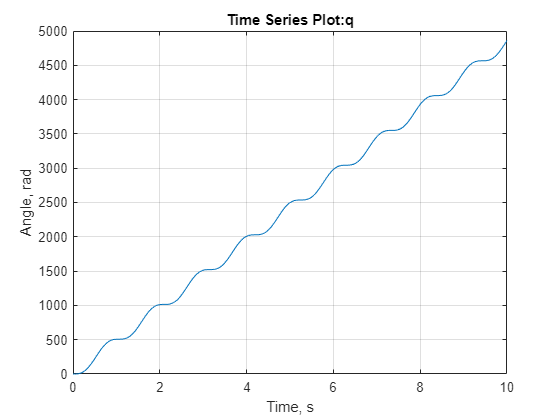


gplot(o.q, 'Time, s', 'Angle, rad')

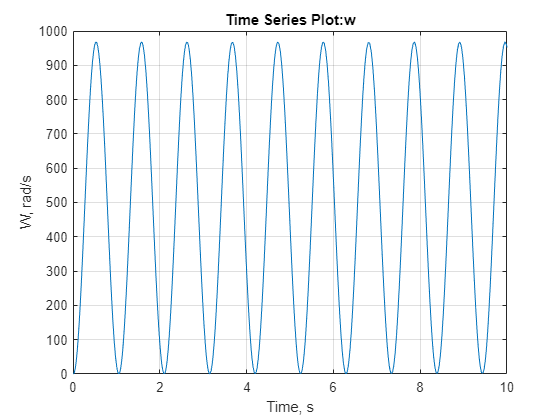

gplot(o.w, 'Time, s', 'W, rad/s')

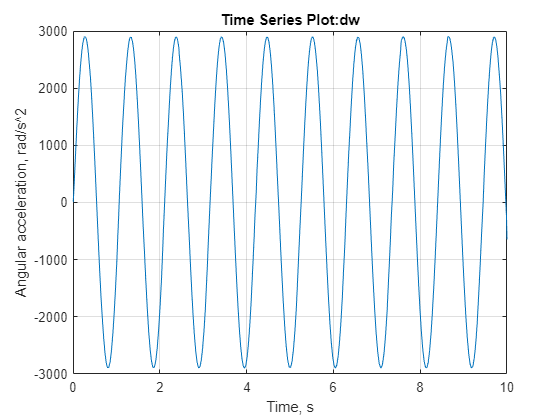

gplot(o.dw, 'Time, s', 'Angular acceleration, rad/s^2')

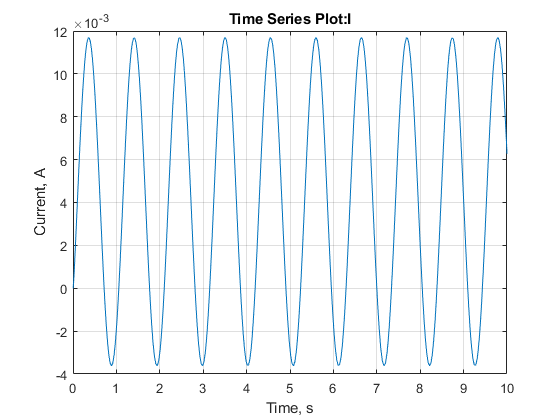

gplot(o.I, 'Time, s', 'Current, A')

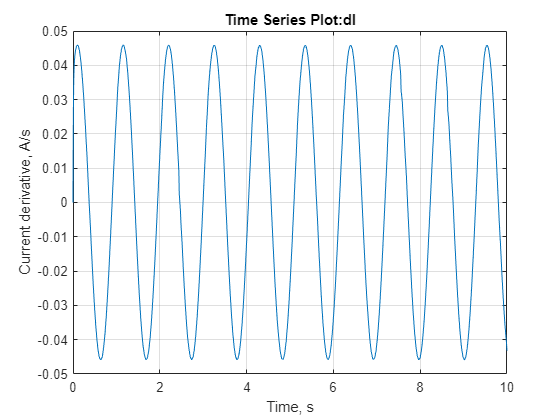

gplot(o.dI, 'Time, s', 'Current derivative, A/s')

### Записываем параметры, полученные из оценки. Проводим симуляцию с новыми параметрами, строим графики

n = length(ek.J.Time)

n = 513

eJ = ek.J.Data(n)

eJ = 2.7286e-08

eR = ek.R.Data(n)

eR = 46.0054

eL = ek.L.Data(n)

eL = 9.6903e-04

eKw = ek.K.Data(n)

eKw = 0.0120

eKm = ek.K.Data(n)

eKm = 0.0120

Ihh = 7.88e-3

Ihh = 0.0079

Whh = 969

Whh = 969

eLam = eKm*Ihh/Whh

eLam = 9.7585e-08


Ah = [-eLam/eJ eKm/eJ; -eKw/eL -eR/eL]

Ah = 1.0e+05 *

   -0.0000    4.3978
   -0.0001   -0.4748


Bh = [-1/eJ 0; 0 1/eL]

Bh = 1.0e+07 *

   -3.6649         0
         0    0.0001


C = [1 0; 0 1]

C =      1     0
     0     1


D = [0 0; 0 0]

D =      0     0
     0     0



A

A = 1.0e+05 *

   -0.0000    4.4727
   -0.0001   -0.3932


A = Ah

A = 1.0e+05 *

   -0.0000    4.3978
   -0.0001   -0.4748


B

B = 1.0e+07 *

   -3.6364         0
         0    0.0001


B = Bh

B = 1.0e+07 *

   -3.6649         0
         0    0.0001



out2 = sim('model', 10)

out2 =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                 simout: [1x1 struct] 
                   tout: [350x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


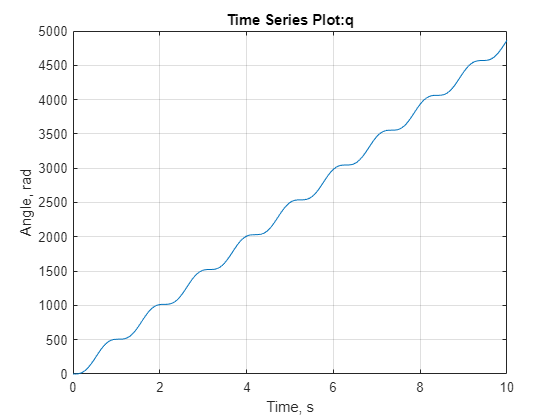

est = out2.simout;

gplot(est.q, 'Time, s', 'Angle, rad')

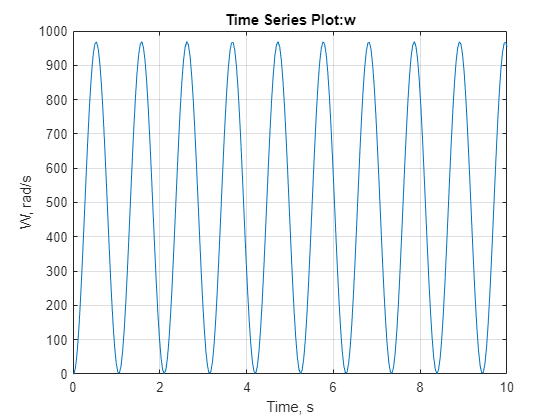

gplot(est.w, 'Time, s', 'W, rad/s')

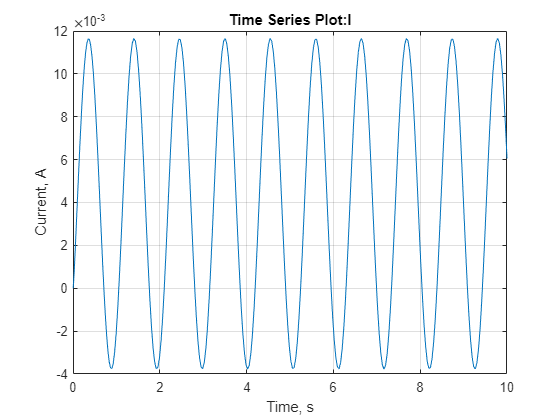

gplot(est.I, 'Time, s', 'Current, A')

### Сравниваем графики

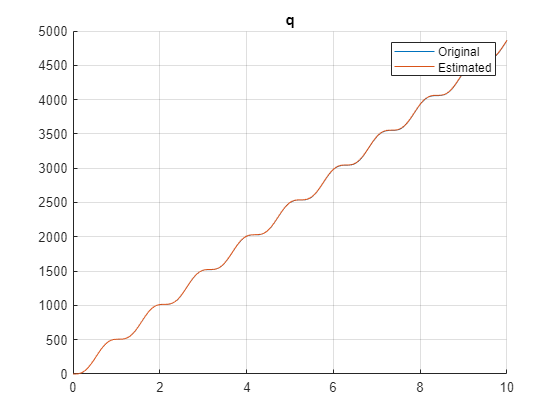

% угол
figure
grid on
hold on;
title("q")
plot(o.q)
plot(est.q)
% xlim([0 0.1])
xlim auto
ylim auto
hold off
legend("Original", "Estimated")

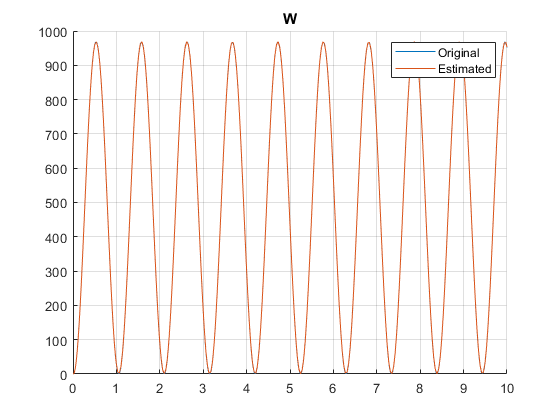


% угловая скорость
figure
grid on
hold on;
title("W")
plot(o.w)
plot(est.w)
% xlim([0 0.1])
xlim auto
ylim auto
hold off
legend("Original", "Estimated")

### Определние параметров по данным из симуляции

% o = out.simout;
% out1 = out;

Th_hat = [0; 0; 0; 0; 0];
dTh_hat = [0; 0; 0; 0; 0];

G_hat = GAMMA_0;
dG_hat = zeros(5,5);

qt = zeros(1, length(out1.tout));

% dTh_hat = G_hat * fi * (u - fi' * Th_hat)
% dG_hat = -G_hat * fi * fi' * G_hat + betta * G_hat

for n = 2:length(out1.tout)
    w_act = o.w.Data(n);
    t = out1.tout(n);
    qt(n) = qt(n-1) + w_act * (t - out1.tout(n-1));

    t = out1.tout(n);
    I_act = o.I.Data(n);
    dI_act = o.dI.Data(n);
    w_act = o.w.Data(n);
    dw_act = o.dw.Data(n);
    u_act = o.u.Data(n);

    phi = [dI_act 0;
           I_act  0;
           w_act -I_act;
           0 dw_act;
           0 w_act];
    phi_T = phi';

    %Gamma G_hat
    dG_hat = -G_hat * phi * phi_T * G_hat + betta * G_hat;
    G_hat = G_hat + dG_hat * (t - out1.tout(n-1));

    U = [u_act; 0];

    Am = -phi_T * Th_hat + U;
    dTh_hat =  G_hat * phi * Am;
    Th_hat = Th_hat + dTh_hat * (t - out1.tout(n-1));
end

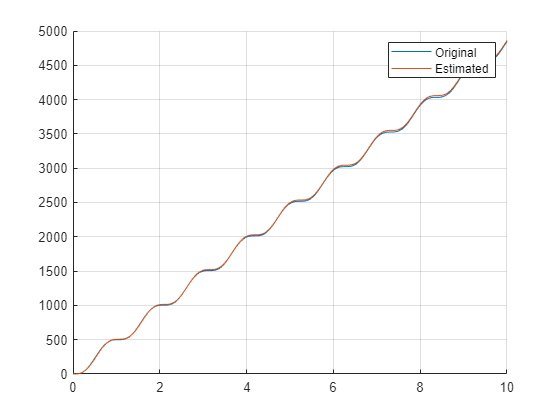

figure
grid on
hold on
plot(out1.tout, qt)
plot(out1.simout.q)
hold off
legend("Original", "Estimated")


Th_hat

Th_hat =     0.0013
   45.9984
    0.0120
    0.0000
    0.0000


L

L = 0.0012

R

R = 46

Kw

Kw = 0.0120

Km

Km = 0.0123

J

J = 2.7500e-08

Lam

Lam = 1.0261e-07


% eL
% eR
% eKw
% eKm
% eJ
% eLam

L_err = L - Th_hat(1)

L_err = -1.4806e-04

R_err = R - Th_hat(2)

R_err = 0.0016

Kw_err = Kw - Th_hat(3)

Kw_err = -1.6823e-08

Rm_err = Km - Th_hat(3)

Rm_err = 2.9998e-04

J_err = J - Th_hat(4)

J_err = 2.1801e-10

Lam_err = Lam - Th_hat(5)

Lam_err = 8.6665e-09